# Logistic Regression

## 1. Logistic regression

Implementation of logistic regression model to predict whether a student gets admitted into a university based on its results on two exams.

The file `data1.txt `contains the dataset for the logistic regression problem. The first two columns contain the exam scores and the third column contains the label.

clear
data = load('data1.txt'); % load data
X = data(:, [1, 2]); 
y = data(:, 3);

### 1.1 Visualizing the data

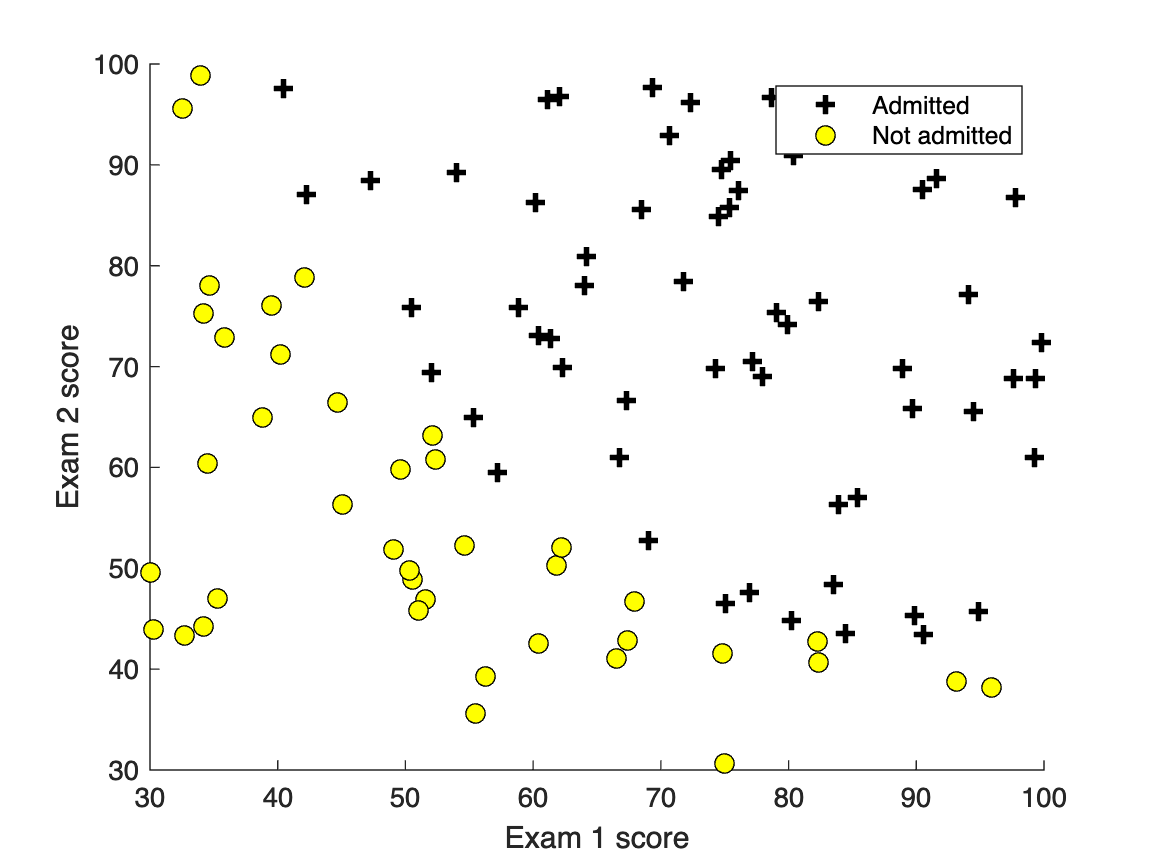

% plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples
plotData(X, y);
 
% labels and legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Sigmoid function

Logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


sigmoid(0) % sigmoid function test

ans = 0.5000

#### 1.2.2 Cost function and gradient

The cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


#### 1.2.3 Initialize the data

% setup the data matrix appropriately
[m, n] = size(X);

% add intercept term to X
X = [ones(m, 1) X];

% initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

#### 1.2.4 Compute the gradient

% compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); 

Gradient at initial theta (zeros):


disp(grad);

   -0.1000
  -12.0092
  -11.2628



% compute and display cost and gradient with non-zero theta
test_theta = [-24; 0.2; 0.2];
[cost, grad] = costFunction(test_theta, X, y);
fprintf('\nCost at non-zero test theta: %f\n', cost);


Cost at non-zero test theta: 0.218330


disp('Gradient at non-zero theta:'); disp(grad);

Gradient at non-zero theta:
    0.0429
    2.5662
    2.6468



#### 1.2.5 Learning parameters using `fminunc`

We will use a MATLAB built-in function called `fminunc i`nstead of taking gradient descent steps to find the optimal parameters.

% set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

% run fminunc to obtain the optimal theta
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:'); disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



### 1.3 **Plotting the decision boundary**

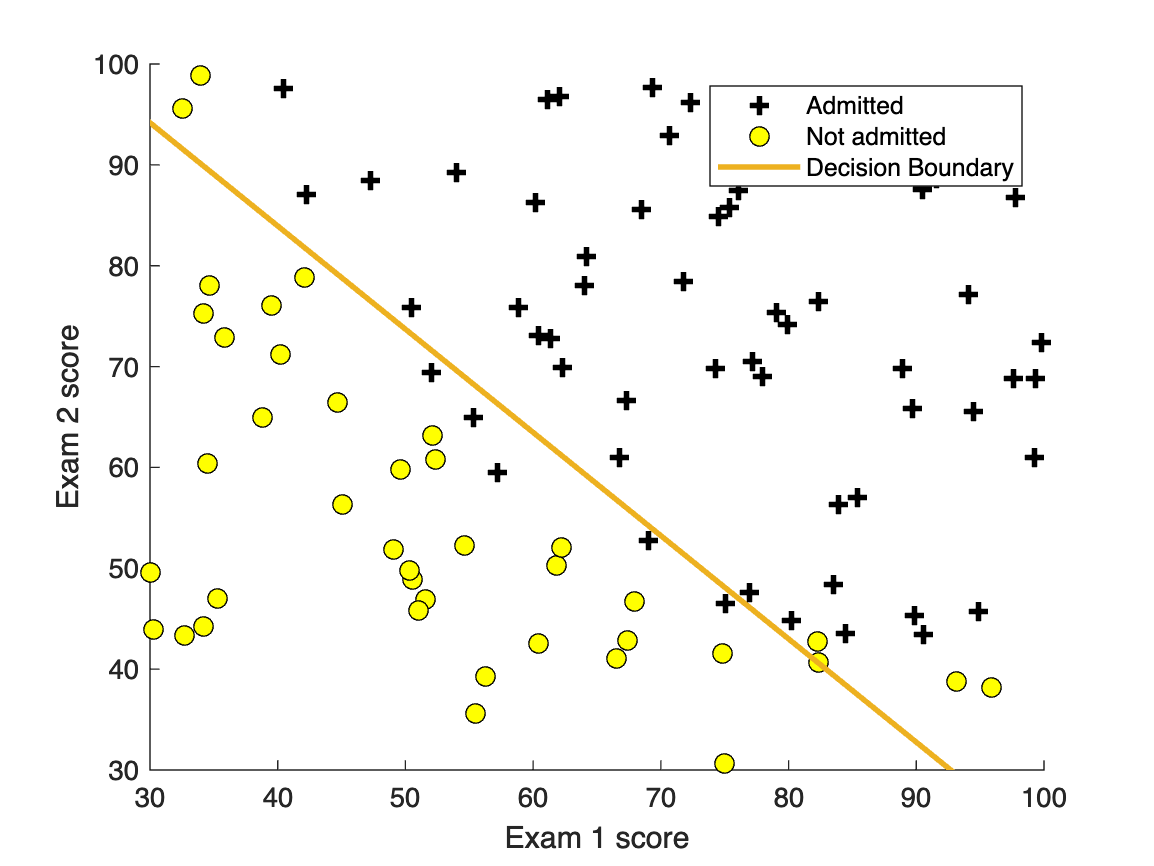

% plot boundary
plotDecisionBoundary(theta, X, y);

hold on;
xlabel('Exam 1 score')
ylabel('Exam 2 score')
legend('Admitted', 'Not admitted','Decision Boundary')
hold off;

### 1.4 Evaluating logistic regression

After learning the parameters, we can use the model to predict whether a particular student will be admitted.

% predict probability for a student with score 45 on exam 1 and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);
fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291



Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set.

% compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


## 2. Regularized logistic regression

Implementation of regularized logistic regression to predict whether cylinder engines from a manufacturing plant pass quality assurance according to their results on two different test.

### 2.1 Visualizing the data

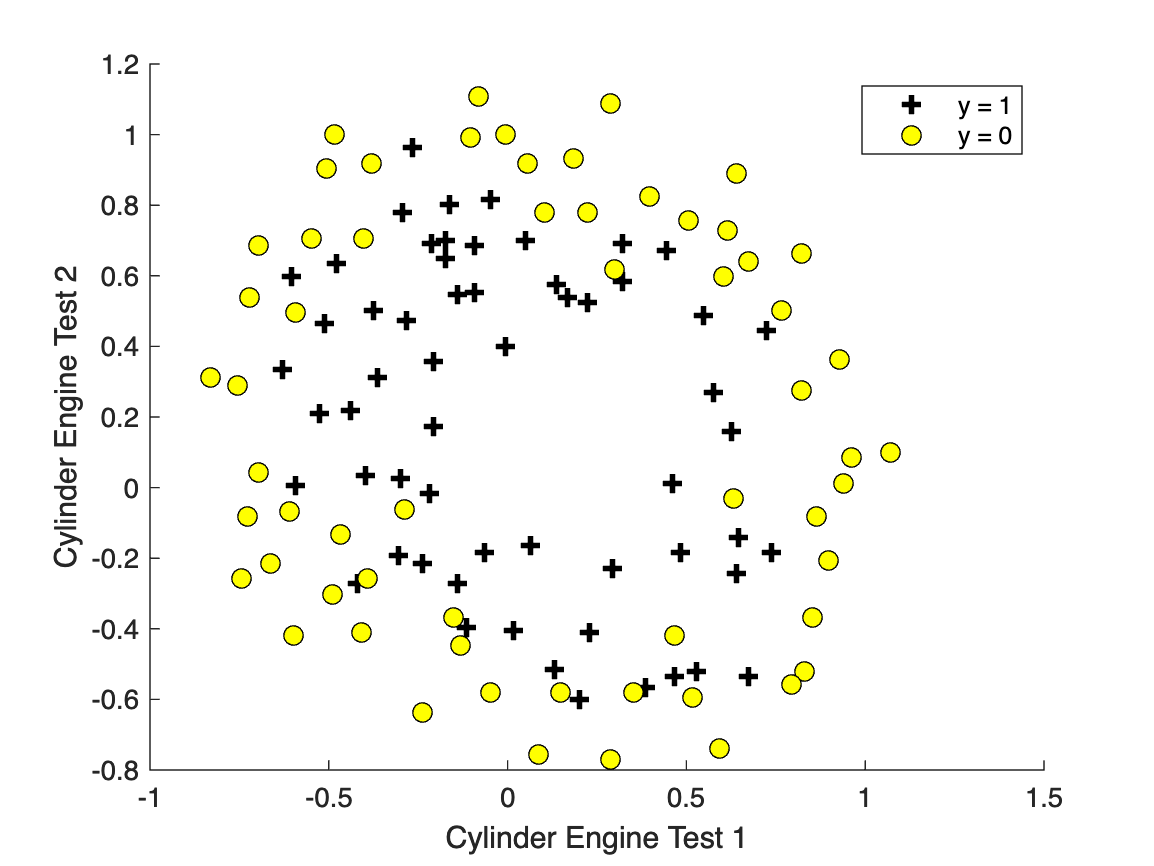

clear
data = load('data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

% plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples
plotData(X, y);

hold on;
xlabel('Cylinder Engine Test 1')
ylabel('Cylinder Engine Test 2')
legend('y = 1', 'y = 0')
hold off;

It can be seen that our dataset cannot be separated into positive and negative examples by a straight-line through the plot.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. So we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\mathrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


As a result of this mapping, our vector of two features (the scores on two quality assurance tests) has been transformed into a 28-dimensional vector.

% add polynomial features
X = mapFeature(X(:,1), X(:,2));

### 2.3 Cost function and gradient

The regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that we do not regularize the parameter $\theta_0$. 

The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


% initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% set regularization parameter lambda to 1
lambda = 1;

% compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Gradient at initial theta (zeros) - first five values only:\n');

Gradient at initial theta (zeros) - first five values only:


fprintf(' %f \n', grad(1:5));

 0.008475 
 0.018788 
 0.000078 
 0.050345 
 0.011501 


% compute and display cost and gradient with all-ones theta and lambda = 10
test_theta = ones(size(X,2),1);
[cost, grad] = costFunctionReg(test_theta, X, y, 10);
fprintf('\nCost at test theta (with lambda = 10): %f\n', cost);


Cost at test theta (with lambda = 10): 3.164509


fprintf('Gradient at test theta - first five values only:\n');

Gradient at test theta - first five values only:


fprintf(' %f \n', grad(1:5));

 0.346045 
 0.161352 
 0.194796 
 0.226863 
 0.092186 


#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, we use `fminunc` to learn the optimal parameters.

% initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 1;
% set options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('\nCost at optimal theta (with lambda = 1): %f\n', J);


Cost at optimal theta (with lambda = 1): 0.529003


### **2.4 Plotting the decision boundary**

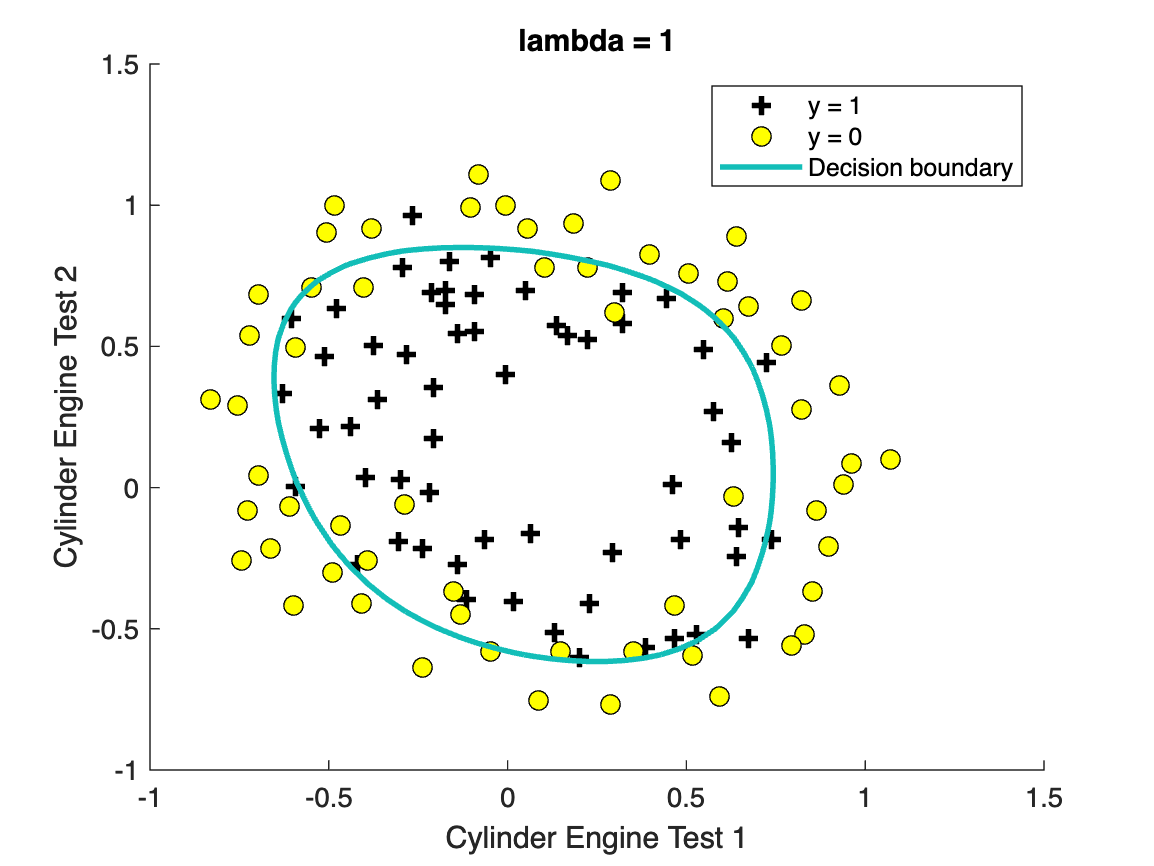

% plot boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

xlabel('Cylinder Engine Test 1')
ylabel('Cylinder Engine Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

It can be noticed that with a small *λ*, the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data . And with a larger *λ*, plot shows a simpler decision boundary which still separates the positives and negatives fairly well. However, if *λ* is set to too high a value, we do not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data.

### 2.5 Evaluating regularized logistic regression

% compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.050847
